clc;
close all;
clear;
load("robot.mat");

Initial cube position: 0,250,55

Intermediate: ???

Final cube position: 0,300,55

### strategy:

pos 0: 0,0,0,0,0,0

#### position 1:    0,250,                         

pos 1 joint angle : 90, 53, -10, 0, -46.7, 0

#### position 2:    0, 250, 55   

pos 2 joint angle : 90, 58, -10, 0, -46.7, 0

#### ----------------pump on----------------

#### position 3:                           

joint angle: 90, 50, -10, 0, -46.7, 0

#### position 4:                           

joint angle: 90, 70, -35, 0, -51.7, 0

#### position 5:   0, 300, 55   

joint angle: 90, 70, -32, 0, -58.7, 0

#### ----------------pump off----------------

#### position 6:                           

joint angle: 90, 65, -32, 0, -58.7, 0

%calculate joint angle
target_points = []


target_points =

     []



%joint angle
theta_list = [ 90, 53, -10, 0, -46.7, 0;
               90, 58, -10, 0, -46.7, 0;
               90, 50, -10, 0, -46.7, 0;
               90, 70, -35, 0, -51.7, 0;
               90, 70, -32, 0, -58.7, 0;
               90, 65, -32, 0, -58.7, 0]';
theta_list = theta_list*pi/180;
num_joint_angle = size(theta_list,2);

#### angle transform

homeconfig = homeConfiguration(robot);
for i = 1:num_joint_angle 
    theta_list(:,i) = homeconfig + theta_list(:,i);
end
theta_list

theta_list =     1.5708    1.5708    1.5708    1.5708    1.5708    1.5708
   -0.6458   -0.5585   -0.6981   -0.3491   -0.3491   -0.4363
   -0.1745   -0.1745   -0.1745   -0.6109   -0.5585   -0.5585
         0         0         0         0         0         0
    0.7557    0.7557    0.7557    0.6685    0.5463    0.5463
         0         0         0         0         0         0


Step = 30;
tip_positions = zeros([Step*num_joint_angle,3]);
total_steps = Step * num_joint_angle;
num_joints = length(homeconfig);

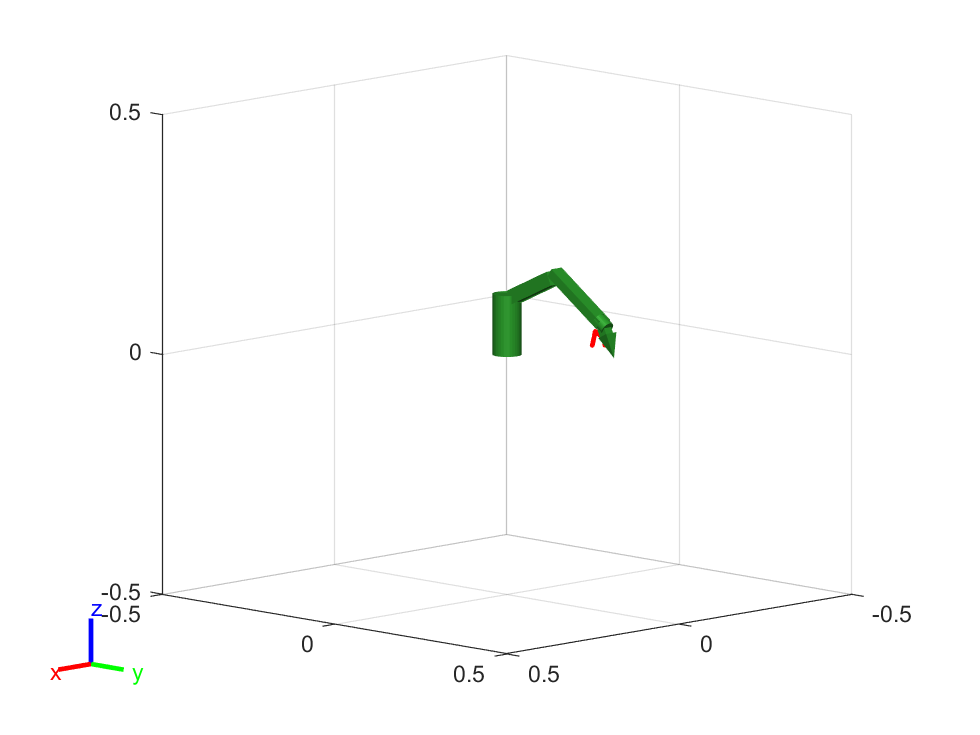

fig = figure('Color', [1 1 1]);
ax = axes('Parent', fig, 'DataAspectRatio', [1 1 1], 'XLim', [-0.5 0.5], 'YLim', [-0.5 0.5], 'ZLim', [-0.5 0.5]);
set(ax, 'XDir','reverse', 'YDir','reverse', 'ZDir','normal');
lighting gouraud;
light('Position',[1 1 1],'Style','infinite');
material dull;  
view(3);
view(ax, -45, 10);
grid on;
hold(ax, 'on');
zoom on;
pan on;
robotPlot = show(robot, theta_list(:,1), 'Parent', ax, 'PreservePlot', false);
trajectoryPlot = plot3(ax, NaN, NaN, NaN, 'r', 'LineWidth', 2);

v = VideoWriter('Task4.avi');
v.FrameRate = 15;
open(v);
for j = 2:num_joint_angle 
    Qd = theta_list(:,j)-theta_list(:,j-1);
    idx = (j-2)*Step;
    for i = 1:Step
        q = theta_list(:,j-1) + Qd / Step * i;
        tip_positions(i+idx,:) = cal_tip_positions(q);
        show(robot, q, 'Parent', ax, 'PreservePlot', false, "Collisions","on","Frames","off");
        set(trajectoryPlot, 'XData', tip_positions(1:i+idx, 1), 'YData', tip_positions(1:i+idx, 2), 'ZData', tip_positions(1:i+idx, 3));
        drawnow;

        frame = getframe(gcf);
        writeVideo(v, frame);
    end
end
hold(ax, 'off');

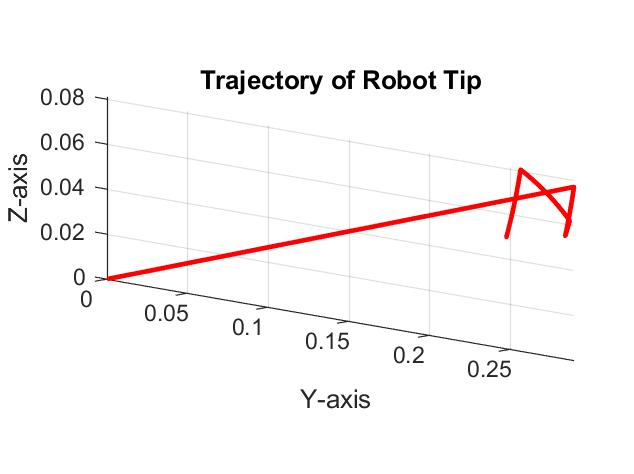

close(v);
figure('Color', [1 1 1]);
plot3(tip_positions(:, 1), tip_positions(:, 2), tip_positions(:, 3), 'r', 'LineWidth', 2);
grid on;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory of Robot Tip');
axis equal;
view(135, 10); 

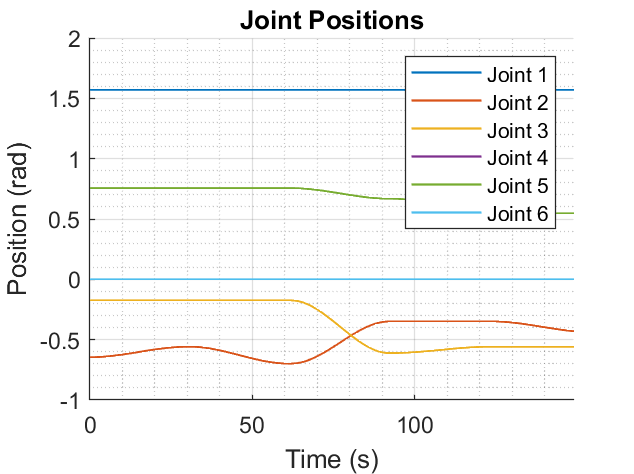

joint_positions = [];
joint_velocities = [];
for i = 1:num_joints
    for j = 2:num_joint_angle 
        [pos, vel] = calculateJointMotion(theta_list(:,j-1), theta_list(:,j), Step);
        joint_positions = [joint_positions, pos];
        joint_velocities = [joint_velocities, vel];
    end  
end

t = 0:(size(joint_positions, 2) - 1);
figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_positions(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, (num_joint_angle-1)*Step - 1]);
title("Joint Positions");
xlabel("Time (s)");
ylabel("Position (rad)");
legend;

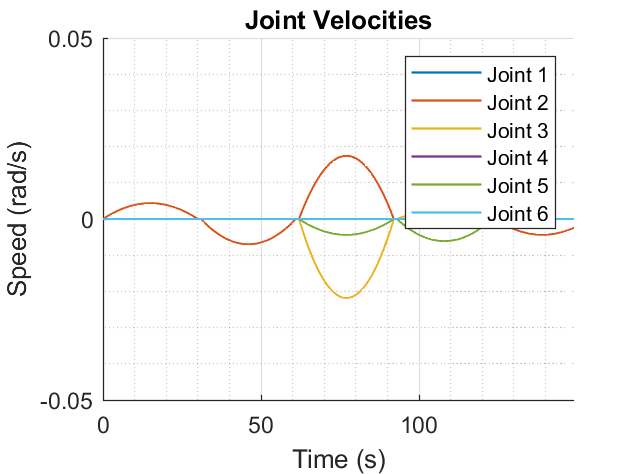


figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_velocities(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, (num_joint_angle-1)*Step - 1]);
ylim([-0.05,0.05]);
title("Joint Velocities");
xlabel("Time (s)");
ylabel("Speed (rad/s)");
legend;

Task4_theta_list = theta_list;
Task4_theta_list(2,:) = Task4_theta_list(2,:) + pi/2;
Task4_theta_list(5,:) = Task4_theta_list(5,:) - pi/2;
save("Task4_theta_list.mat","Task4_theta_list");